## ARIMA Model

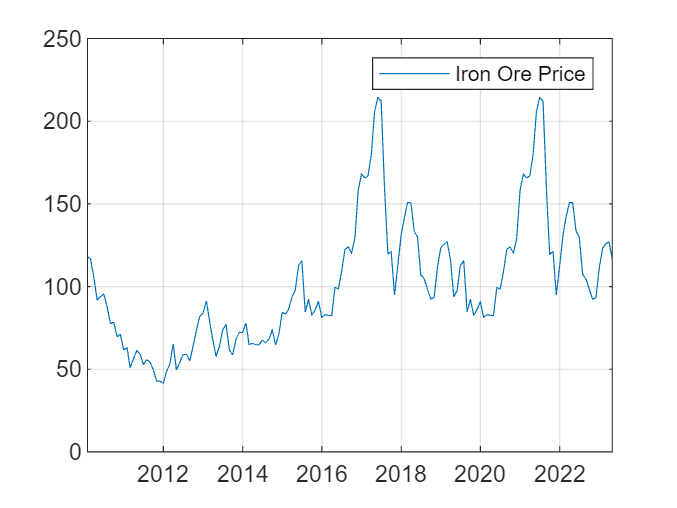

% Create data for ARIMA Model

data = readtable("iron_ore.xlsx");

t = data.Date(:);
price = data.Price(:);

figure
plot(t,price,'-','DisplayName','Iron Ore Price')
legend, grid 

% ARIMA model

mdl1 = arima(1,1,1);
mdl2 = arima(2,1,0);

estMdl1 = estimate(mdl1,price);

 
    ARIMA(1,1,1) Model (Gaussian Distribution):
 
                  Value      StandardError    TStatistic      PValue  
                _________    _____________    __________    __________

    Constant    -0.032585        1.2927       -0.025206        0.97989
    AR{1}         0.17519       0.28041         0.62477        0.53212
    MA{1}         0.12067       0.26852         0.44938        0.65316
    Variance       153.02        12.343          12.398     2.6845e-35



estMdl2 = estimate(mdl2,price);

 
    ARIMA(2,1,0) Model (Gaussian Distribution):
 
                  Value      StandardError    TStatistic      PValue  
                _________    _____________    __________    __________

    Constant    -0.026492        1.1573       -0.022891        0.98174
    AR{1}         0.29971      0.064831          4.6229     3.7842e-06
    AR{2}       -0.051149      0.066301        -0.77147        0.44043
    Variance       152.88        12.585          12.148     5.8974e-34



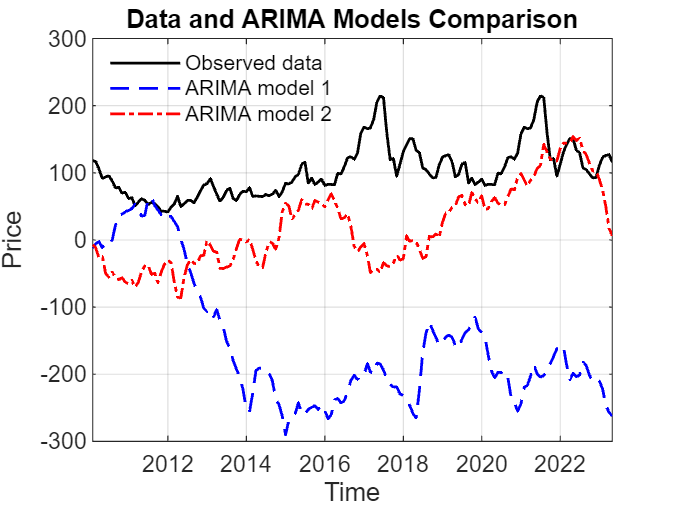


y1 = simulate(estMdl1,length(price));
y2 = simulate(estMdl2,length(price));

figure();
plot(t, price, 'k', 'LineWidth',1.2); hold on
plot(t, y1, 'b--', 'LineWidth',1.2);
plot(t, y2, 'r-.', 'LineWidth',1.2);

grid on
xlabel('Time');
ylabel('Price');
title('Data and ARIMA Models Comparison');
legend({'Observed data','ARIMA model 1','ARIMA model 2'}, ...
       'Location','best','Box','off');